# **Final Project**

# **Part 1 - Automatic Zebra Crossing Recognition**

## **Reading images**

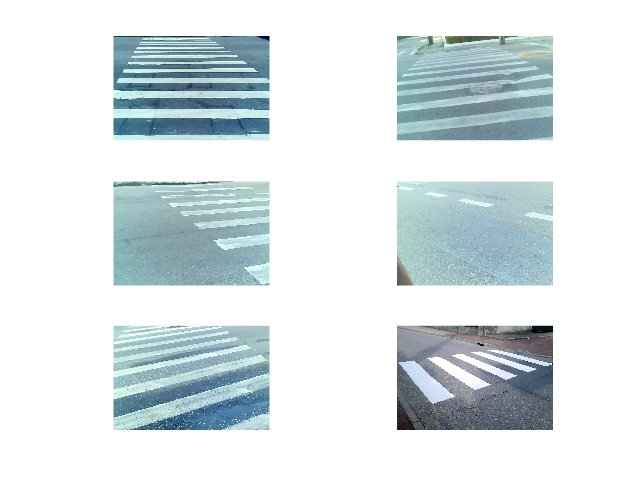

% Create three lists respectively for: original images, black and
% white images, and binary images.
imlist = cell(6);
imlistgray = cell(6);
imlistbw = cell(6);

% For each image, store it in the `imlist` list, resize it and display
% it in a subplot.
figure;
for i=1:6
    imlist{i} = imread("./part1 images/image" + i + ".jpg");

    imlist{i} = imresize(imlist{i}, [720 1080]);

    subplot(3,2,i)
    imshow(imlist{i})
end

## Converting images to black and white

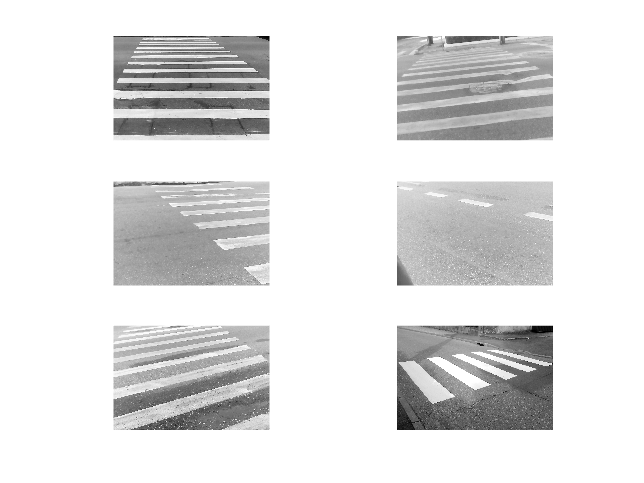

% For each image, convert it in black and white (if it is not already) and
% display it in a subplot.
figure;
for i = 1:6
    if size(imlist{i}, 3) == 3
        imlistgray{i} = rgb2gray(imlist{i});
    else
        imlistgray{i} = imlistgray{i};
    end

    subplot(3,2,i)
    imshow(imlistgray{i})
end

## Binarizing images

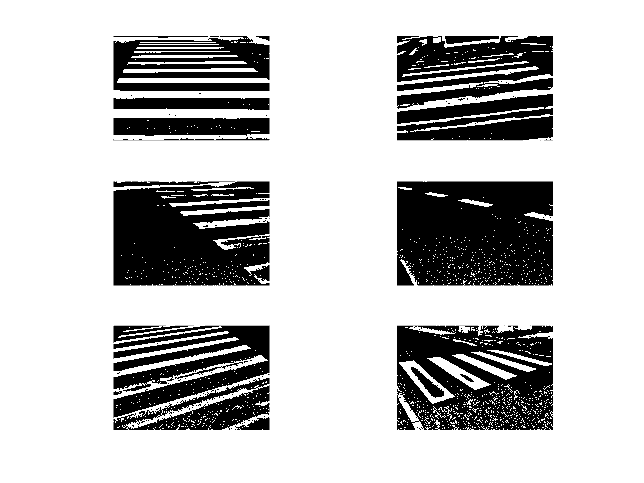

% For each image, binarize it using the 'adaptive' method. Then, display
% it.
figure;
for i=1:6
    imlistbw{i} = imbinarize(imlistgray{i}, 'adaptive');
    
    subplot(3,2,i)
    imshow(imlistbw{i});
end

## Cleaning images

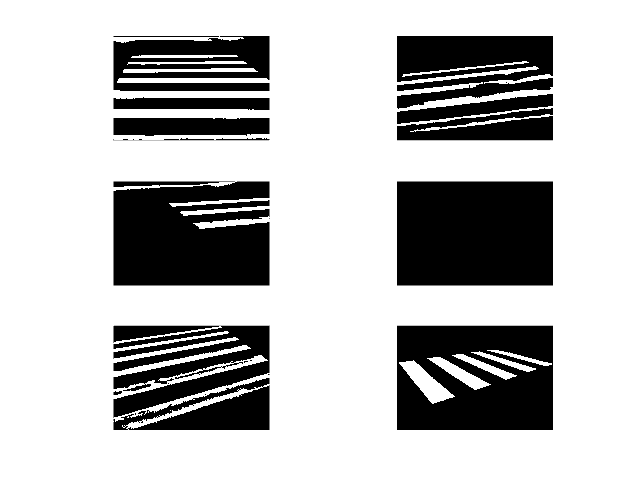

% For each binary image, delete small shapes (less than 10000 pixels)
% and fill all the holes. Then, display it in a subplot.
figure;
for i = 1:6
    imlistbw{i} = bwareaopen(imlistbw{i}, 10000);
    imlistbw{i} = imfill(imlistbw{i}, 'holes');

    subplot(3,2,i)
    imshow(imlistbw{i})
end

## Surrounding the zebra crossing

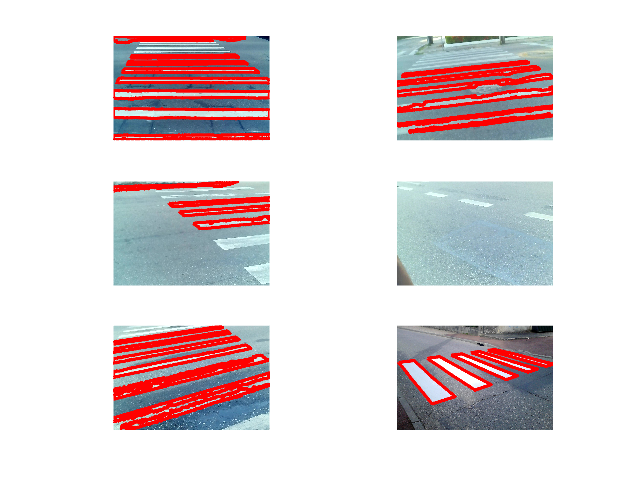

% For each binary image, look for the boundaries and plot it on the
% original image in a subplot.
figure;
for i = 1:6
    B = bwboundaries(imlistbw{i});
    
    subplot(3,2,i)
    imshow(imlist{i})
    
    hold on;
    for k = 1:length(B)
       boundary = B{k};
       plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2)
    end
    hold off;
end